% Date created: 221215

% This script takes SPT data from HaloTag-PBP2B and makes violin DABEST
% plots of processivities across various conditions.

## User parameters

speedcut = [5 50]; % [nm/s]
interval = 1; % [s] acquisition interval

## Load data

datadir = '\\campus\rdw\FMS CBCB\nsh167\Shared\data\Whitley-Kevin\Data_Analyzed\PBP2B_results\';

cdm30_file = '221128_sh147_cdm_30c_vercini_kymo_unreg_clean_polyline.mat';
cdm37_file = '221207_sh147_cdm_37c_vercini_kymo_unreg_clean_polyline.mat';
phmm30_file = '221111_sh147_phmm_30c_vercini_kymo_unreg_clean_polyline.mat';
phmm37_file = '221122_sh147_phmm_37c_vercini_kymo_unreg_clean_polyline.mat';

pc19_file = '221115_sh147_phmm_30c_pc19_vercini_kymo_unreg_clean_polyline.mat';
penG_file = '221116_sh147_phmm_30c_penG_vercini_kymo_unreg_clean_polyline.mat';
fos_file = '221116_sh147_phmm_30c_fosfomycin_vercini_kymo_unreg_clean_polyline.mat';
g106s_file = '221208_sh147sh056_phmm_30c_vercini_kymo_unreg_clean_polyline.mat';

open([datadir cdm30_file])

ans = struct with fields:
    cdm30_life: [1016×16 table]


open([datadir cdm37_file])

ans = struct with fields:
    cdm37_life: [1542×16 table]


open([datadir phmm30_file])

ans = struct with fields:
    phmm30_life: [1572×16 table]


open([datadir phmm37_file])

ans = struct with fields:
    phmm37_life: [1996×16 table]



open([datadir pc19_file])

ans = struct with fields:
    phmm30_pc19_life: [1337×16 table]


open([datadir penG_file])

ans = struct with fields:
    phmm30_penG_life: [1537×16 table]


open([datadir fos_file])

ans = struct with fields:
    phmm30_fos_life: [1167×16 table]


open([datadir g106s_file])

ans = struct with fields:
    phmm30_g106s_life: [362×16 table]


## Get processivities

% ALL SINGLE SEGMENT PROCESSIVITIES

cdm30_seg_proc = abs(cdm30_life.Length_nm_(abs(cdm30_life.Speed_nm_s_)>speedcut(1) & abs(cdm30_life.Speed_nm_s_)<speedcut(2) & cdm30_life.Segment_~=0));
cdm37_seg_proc = abs(cdm37_life.Length_nm_(abs(cdm37_life.Speed_nm_s_)>speedcut(1) & abs(cdm37_life.Speed_nm_s_)<speedcut(2) & cdm37_life.Segment_~=0));
phmm30_seg_proc = abs(phmm30_life.Length_nm_(abs(phmm30_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_life.Speed_nm_s_)<speedcut(2) & phmm30_life.Segment_~=0));
phmm37_seg_proc = abs(phmm37_life.Length_nm_(abs(phmm37_life.Speed_nm_s_)>speedcut(1) & abs(phmm37_life.Speed_nm_s_)<speedcut(2) & phmm37_life.Segment_~=0));

pc19_seg_proc = abs(phmm30_pc19_life.Length_nm_(abs(phmm30_pc19_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_pc19_life.Speed_nm_s_)<speedcut(2) & phmm30_pc19_life.Segment_~=0));
penG_seg_proc = abs(phmm30_penG_life.Length_nm_(abs(phmm30_penG_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_penG_life.Speed_nm_s_)<speedcut(2) & phmm30_penG_life.Segment_~=0));
fos_seg_proc = abs(phmm30_fos_life.Length_nm_(abs(phmm30_fos_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_fos_life.Speed_nm_s_)<speedcut(2) & phmm30_fos_life.Segment_~=0));
g106s_seg_proc = abs(phmm30_g106s_life.Length_nm_(abs(phmm30_g106s_life.Speed_nm_s_)>speedcut(1) & abs(phmm30_g106s_life.Speed_nm_s_)<speedcut(2) & phmm30_g106s_life.Segment_~=0));

% ONLY MIDDLE SEGMENT PROCESSIVITIES

cdm30_middle_seg = getKymotraceMiddleSegments(cdm30_life, interval);
cdm37_middle_seg = getKymotraceMiddleSegments(cdm37_life, interval);
phmm30_middle_seg = getKymotraceMiddleSegments(phmm30_life, interval);
phmm37_middle_seg = getKymotraceMiddleSegments(phmm37_life, interval);

pc19_middle_seg = getKymotraceMiddleSegments(phmm30_pc19_life, interval);
penG_middle_seg = getKymotraceMiddleSegments(phmm30_penG_life, interval);
fos_middle_seg = getKymotraceMiddleSegments(phmm30_fos_life, interval);
g106s_middle_seg = getKymotraceMiddleSegments(phmm30_g106s_life, interval);

cdm30_mid_seg_proc = abs(cdm30_middle_seg.Length_nm_(abs(cdm30_middle_seg.Speed_nm_s_)>speedcut(1) & abs(cdm30_middle_seg.Speed_nm_s_)<speedcut(2) & cdm30_middle_seg.Segment_~=0));
cdm37_mid_seg_proc = abs(cdm37_middle_seg.Length_nm_(abs(cdm37_middle_seg.Speed_nm_s_)>speedcut(1) & abs(cdm37_middle_seg.Speed_nm_s_)<speedcut(2) & cdm37_middle_seg.Segment_~=0));
phmm30_mid_seg_proc = abs(phmm30_middle_seg.Length_nm_(abs(phmm30_middle_seg.Speed_nm_s_)>speedcut(1) & abs(phmm30_middle_seg.Speed_nm_s_)<speedcut(2) & phmm30_middle_seg.Segment_~=0));
phmm37_mid_seg_proc = abs(phmm37_middle_seg.Length_nm_(abs(phmm37_middle_seg.Speed_nm_s_)>speedcut(1) & abs(phmm37_middle_seg.Speed_nm_s_)<speedcut(2) & phmm37_middle_seg.Segment_~=0));

pc19_mid_seg_proc = abs(pc19_middle_seg.Length_nm_(abs(pc19_middle_seg.Speed_nm_s_)>speedcut(1) & abs(pc19_middle_seg.Speed_nm_s_)<speedcut(2) & pc19_middle_seg.Segment_~=0));
penG_mid_seg_proc = abs(penG_middle_seg.Length_nm_(abs(penG_middle_seg.Speed_nm_s_)>speedcut(1) & abs(penG_middle_seg.Speed_nm_s_)<speedcut(2) & penG_middle_seg.Segment_~=0));
fos_mid_seg_proc = abs(fos_middle_seg.Length_nm_(abs(fos_middle_seg.Speed_nm_s_)>speedcut(1) & abs(fos_middle_seg.Speed_nm_s_)<speedcut(2) & fos_middle_seg.Segment_~=0));
g106s_mid_seg_proc = abs(g106s_middle_seg.Length_nm_(abs(g106s_middle_seg.Speed_nm_s_)>speedcut(1) & abs(g106s_middle_seg.Speed_nm_s_)<speedcut(2) & g106s_middle_seg.Segment_~=0));

% CUMULATIVE PROCESSIVITIES (FULL TRACKS)

cdm30_full = fullTrackProcessivity(cdm30_life, speedcut);
cdm37_full = fullTrackProcessivity(cdm37_life, speedcut);
phmm30_full = fullTrackProcessivity(phmm30_life, speedcut);
phmm37_full = fullTrackProcessivity(phmm37_life, speedcut);

pc19_full = fullTrackProcessivity(phmm30_pc19_life, speedcut);
penG_full = fullTrackProcessivity(phmm30_penG_life, speedcut);
fos_full = fullTrackProcessivity(phmm30_fos_life, speedcut);
g106s_full = fullTrackProcessivity(phmm30_g106s_life, speedcut);

cdm30_full_proc = cdm30_full.Total_Length_nm_(~isnan(cdm30_full.Total_Length_nm_));
cdm37_full_proc = cdm37_full.Total_Length_nm_(~isnan(cdm37_full.Total_Length_nm_));
phmm30_full_proc = phmm30_full.Total_Length_nm_(~isnan(phmm30_full.Total_Length_nm_));
phmm37_full_proc = phmm37_full.Total_Length_nm_(~isnan(phmm37_full.Total_Length_nm_));

pc19_full_proc = pc19_full.Total_Length_nm_(~isnan(pc19_full.Total_Length_nm_));
penG_full_proc = penG_full.Total_Length_nm_(~isnan(penG_full.Total_Length_nm_));
fos_full_proc = fos_full.Total_Length_nm_(~isnan(fos_full.Total_Length_nm_));
g106s_full_proc = g106s_full.Total_Length_nm_(~isnan(g106s_full.Total_Length_nm_));

## Prepare for plotting

% ALL SINGLE SEGMENT PROCESSIVITIES

c_cdm30_seg_proc = repmat({'cdm30'}, length(cdm30_seg_proc), 1);
c_cdm37_seg_proc = repmat({'cdm37'}, length(cdm37_seg_proc), 1);
c_phmm30_seg_proc = repmat({'phmm30'}, length(phmm30_seg_proc), 1);
c_phmm37_seg_proc = repmat({'phmm37'}, length(phmm37_seg_proc), 1);

c_pc19_seg_proc = repmat({'pc19'}, length(pc19_seg_proc), 1);
c_penG_seg_proc = repmat({'penG'}, length(penG_seg_proc), 1);
c_fos_seg_proc = repmat({'fos'}, length(fos_seg_proc), 1);
c_g106s_seg_proc = repmat({'g106s'}, length(g106s_seg_proc), 1);

% ONLY MIDDLE SEGMENT PROCESSIVITIES

c_cdm30_mid_seg_proc = repmat({'cdm30'}, length(cdm30_mid_seg_proc), 1);
c_cdm37_mid_seg_proc = repmat({'cdm37'}, length(cdm37_mid_seg_proc), 1);
c_phmm30_mid_seg_proc = repmat({'phmm30'}, length(phmm30_mid_seg_proc), 1);
c_phmm37_mid_seg_proc = repmat({'phmm37'}, length(phmm37_mid_seg_proc), 1);

c_pc19_mid_seg_proc = repmat({'pc19'}, length(pc19_mid_seg_proc), 1);
c_penG_mid_seg_proc = repmat({'penG'}, length(penG_mid_seg_proc), 1);
c_fos_mid_seg_proc = repmat({'fos'}, length(fos_mid_seg_proc), 1);
c_g106s_mid_seg_proc = repmat({'g106s'}, length(g106s_mid_seg_proc), 1);

% CUMULATIVE PROCESSIVITIES (FULL TRACKS)

c_cdm30_full_proc = repmat({'cdm30'}, length(cdm30_full_proc), 1);
c_cdm37_full_proc = repmat({'cdm37'}, length(cdm37_full_proc), 1);
c_phmm30_full_proc = repmat({'phmm30'}, length(phmm30_full_proc), 1);
c_phmm37_full_proc = repmat({'phmm37'}, length(phmm37_full_proc), 1);

c_pc19_full_proc = repmat({'pc19'}, length(pc19_full_proc), 1);
c_penG_full_proc = repmat({'penG'}, length(penG_full_proc), 1);
c_fos_full_proc = repmat({'fos'}, length(fos_full_proc), 1);
c_g106s_full_proc = repmat({'g106s'}, length(g106s_full_proc), 1);

## Plot

delta_name_plot = 1×1 cell array
    {' '}


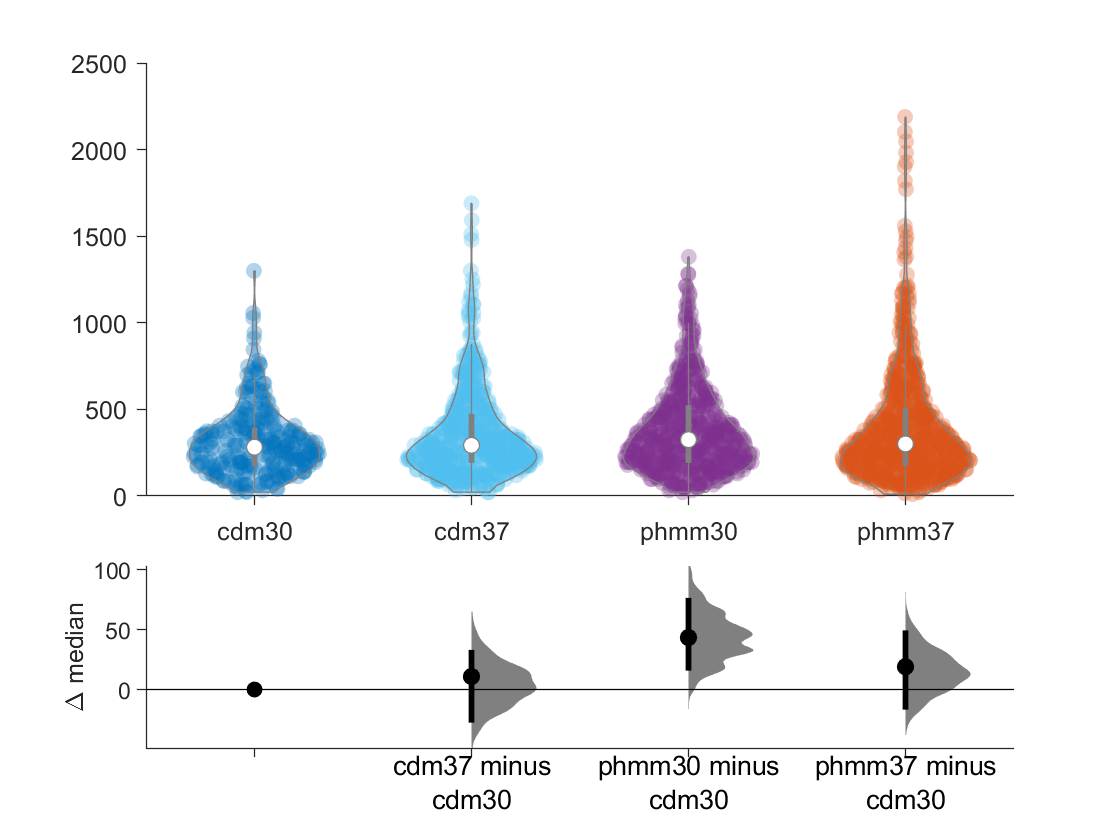

ans = 7×4 table
            Group             Value           CIs            N 
    ______________________    ______    ________________    ___

    {'cdm30'             }    281.67       260    308.75    243
    {'cdm37'             }     292.5    276.25    319.58    508
    {'phmm30'            }       325     292.5    346.67    533
    {'phmm37'            }    300.63    273.54    319.58    692
    {'cdm37 minus cdm30' }    10.833     -32.5    43.333    NaN
    {'phmm30 minus cdm30'}    43.333    5.4166     81.25    NaN
    {'phmm37 minus cdm30'}    18.958    -16.25    54.167    NaN


% ALL SINGLE SEGMENT PROCESSIVITIES

violinplusdabest([cdm30_seg_proc; cdm37_seg_proc; phmm30_seg_proc; phmm37_seg_proc], [c_cdm30_seg_proc; c_cdm37_seg_proc; c_phmm30_seg_proc; c_phmm37_seg_proc],{'cdm30', 'cdm37', 'phmm30', 'phmm37'})

delta_name_plot = 1×1 cell array
    {' '}


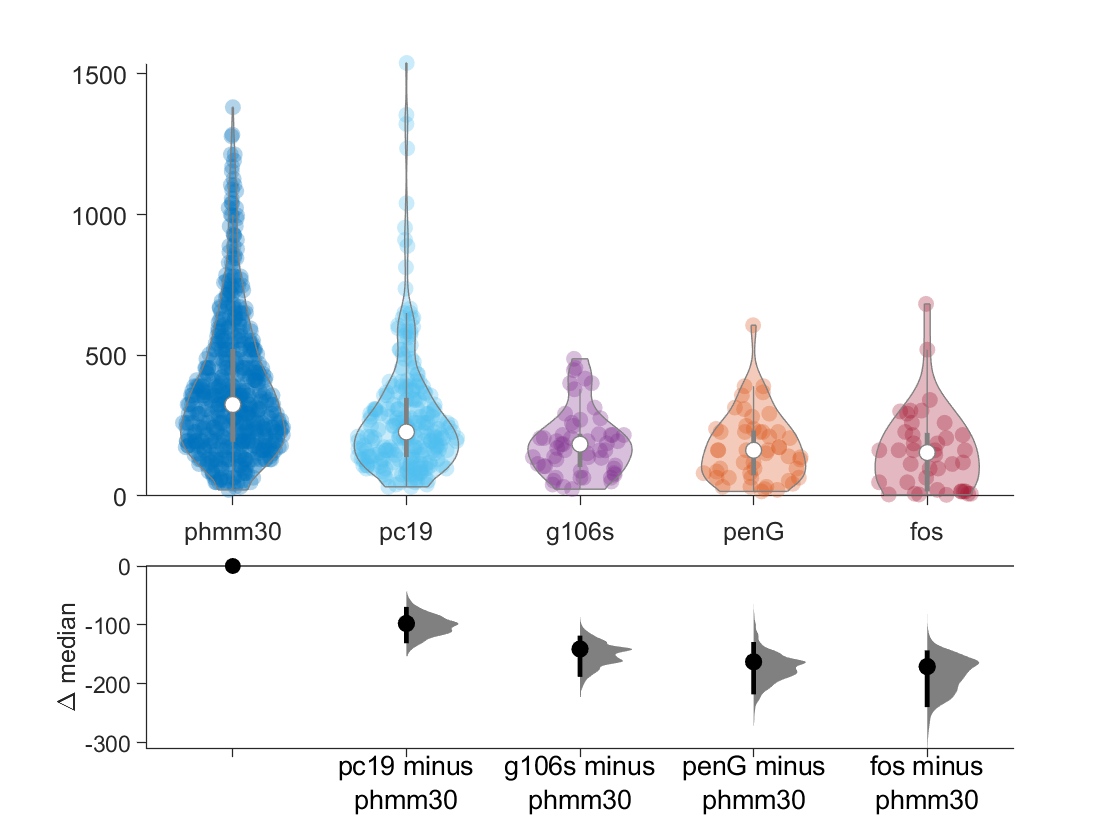

ans = 9×4 table
            Group              Value            CIs             N 
    ______________________    _______    __________________    ___

    {'phmm30'            }        325      292.5     346.67    533
    {'pc19'              }      227.5     211.25     255.94    234
    {'g106s'             }     184.17     140.83     205.83     55
    {'penG'              }      162.5        130      227.5     49
    {'fos'               }     154.38     89.375     186.88     40
    {'pc19 minus phmm30' }      -97.5    -135.42        -65    NaN
    {'g106s minus phmm30'}    -140.83       -195    -113.75    NaN
    {'penG minus phmm30' }     -162.5     -227.5    -113.75    NaN
    {'fos minus phmm30'  }    -170.63    -251.88    -134.06    NaN



violinplusdabest([phmm30_seg_proc; pc19_seg_proc; g106s_seg_proc; penG_seg_proc; fos_seg_proc], [c_phmm30_seg_proc; c_pc19_seg_proc; c_g106s_seg_proc; c_penG_seg_proc; c_fos_seg_proc],{'phmm30', 'pc19', 'g106s', 'penG', 'fos'})

delta_name_plot = 1×1 cell array
    {' '}


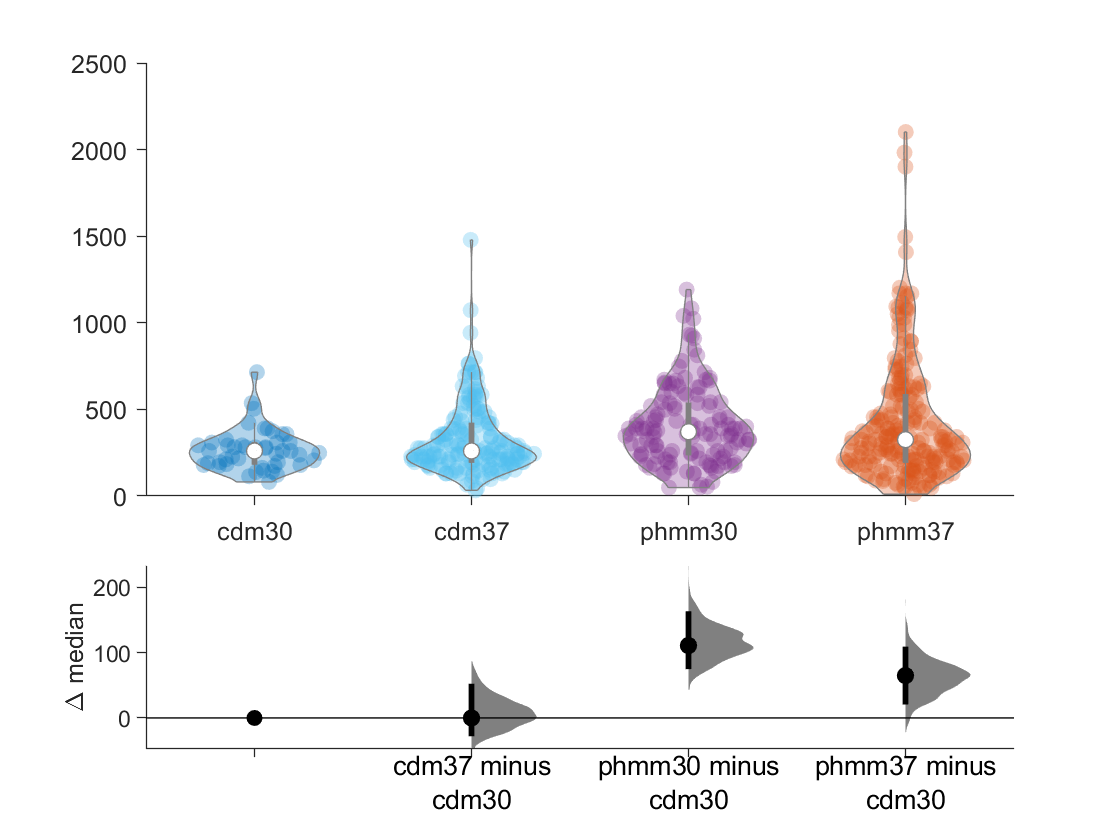

ans = 7×4 table
            Group             Value           CIs            N 
    ______________________    ______    ________________    ___

    {'cdm30'             }       260    213.96    287.08     46
    {'cdm37'             }       260    241.04     292.5    164
    {'phmm30'            }    371.04    335.83       390    136
    {'phmm37'            }       325     292.5     357.5    219
    {'cdm37 minus cdm30' }         0     -32.5    59.583    NaN
    {'phmm30 minus cdm30'}    111.04    66.354    173.33    NaN
    {'phmm37 minus cdm30'}        65    10.833    116.46    NaN



% ONLY MIDDLE SEGMENT PROCESSIVITIES

violinplusdabest([cdm30_mid_seg_proc; cdm37_mid_seg_proc; phmm30_mid_seg_proc; phmm37_mid_seg_proc], [c_cdm30_mid_seg_proc; c_cdm37_mid_seg_proc; c_phmm30_mid_seg_proc; c_phmm37_mid_seg_proc],{'cdm30', 'cdm37', 'phmm30', 'phmm37'})

delta_name_plot = 1×1 cell array
    {' '}


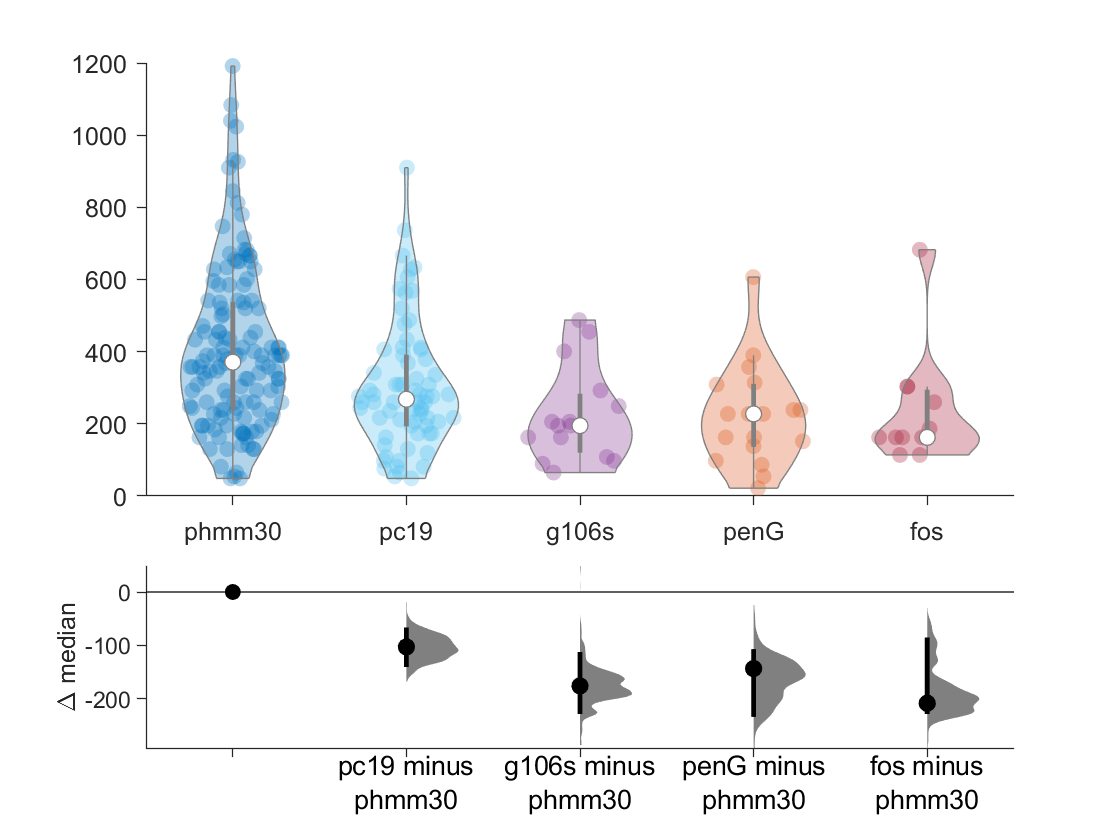

ans = 9×4 table
            Group              Value            CIs             N 
    ______________________    _______    __________________    ___

    {'phmm30'            }     371.04     341.25        390    136
    {'pc19'              }     268.13     238.33     300.63     70
    {'g106s'             }        195     108.33     249.17     15
    {'penG'              }      227.5     157.08     276.25     18
    {'fos'               }      162.5     113.75        260     11
    {'pc19 minus phmm30' }    -102.92    -148.28    -62.292    NaN
    {'g106s minus phmm30'}    -176.04    -243.75      -97.5    NaN
    {'penG minus phmm30' }    -143.54    -239.69    -89.375    NaN
    {'fos minus phmm30'  }    -208.54    -232.92    -67.708    NaN



violinplusdabest([phmm30_mid_seg_proc; pc19_mid_seg_proc; g106s_mid_seg_proc; penG_mid_seg_proc; fos_mid_seg_proc], [c_phmm30_mid_seg_proc; c_pc19_mid_seg_proc; c_g106s_mid_seg_proc; c_penG_mid_seg_proc; c_fos_mid_seg_proc],{'phmm30', 'pc19', 'g106s', 'penG', 'fos'})

delta_name_plot = 1×1 cell array
    {' '}


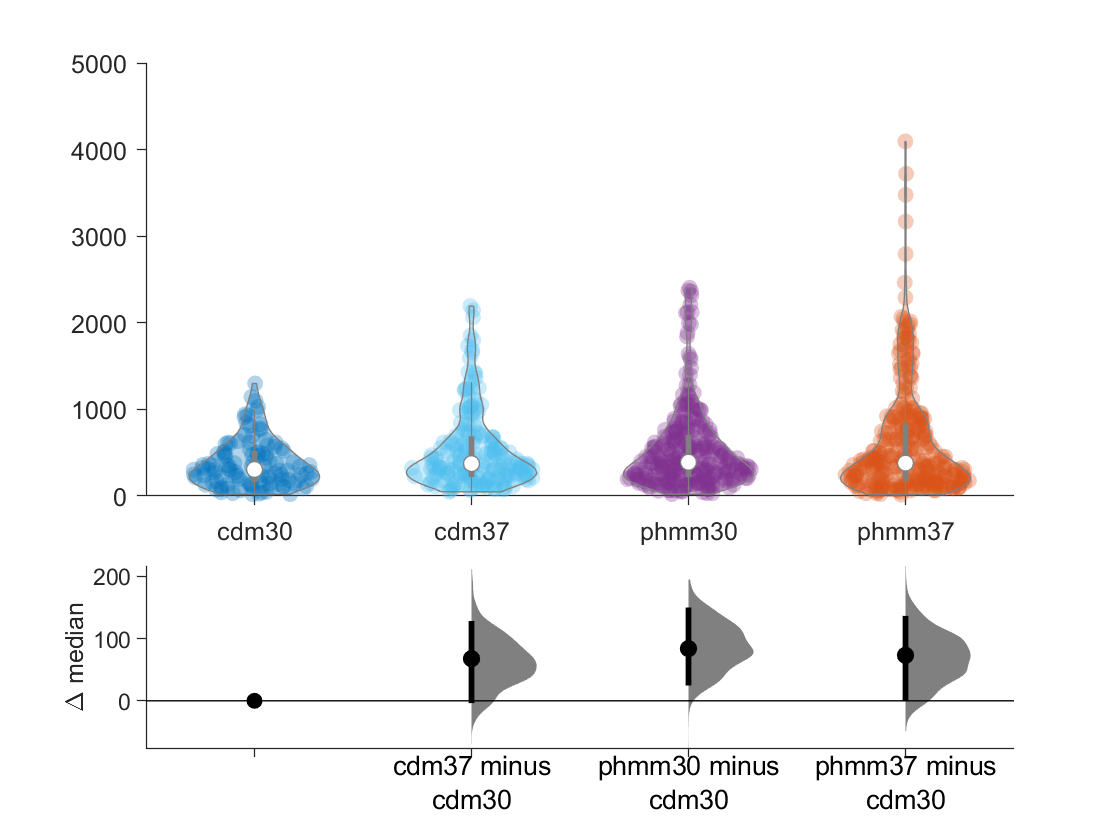

ans = 7×4 table
            Group             Value            CIs             N 
    ______________________    ______    __________________    ___

    {'cdm30'             }    306.04     251.88     358.66    112
    {'cdm37'             }    373.75     338.54     446.88    182
    {'phmm30'            }       390     346.67        455    265
    {'phmm37'            }    379.17     335.83     438.75    301
    {'cdm37 minus cdm30' }    67.708    -14.896      144.9    NaN
    {'phmm30 minus cdm30'}    83.958      16.25     157.08    NaN
    {'phmm37 minus cdm30'}    73.125    -5.4166     150.31    NaN



% CUMULATIVE PROCESSIVITIES (FULL TRACKS)

violinplusdabest([cdm30_full_proc; cdm37_full_proc; phmm30_full_proc; phmm37_full_proc], [c_cdm30_full_proc; c_cdm37_full_proc; c_phmm30_full_proc; c_phmm37_full_proc],{'cdm30', 'cdm37', 'phmm30', 'phmm37'})

delta_name_plot = 1×1 cell array
    {' '}


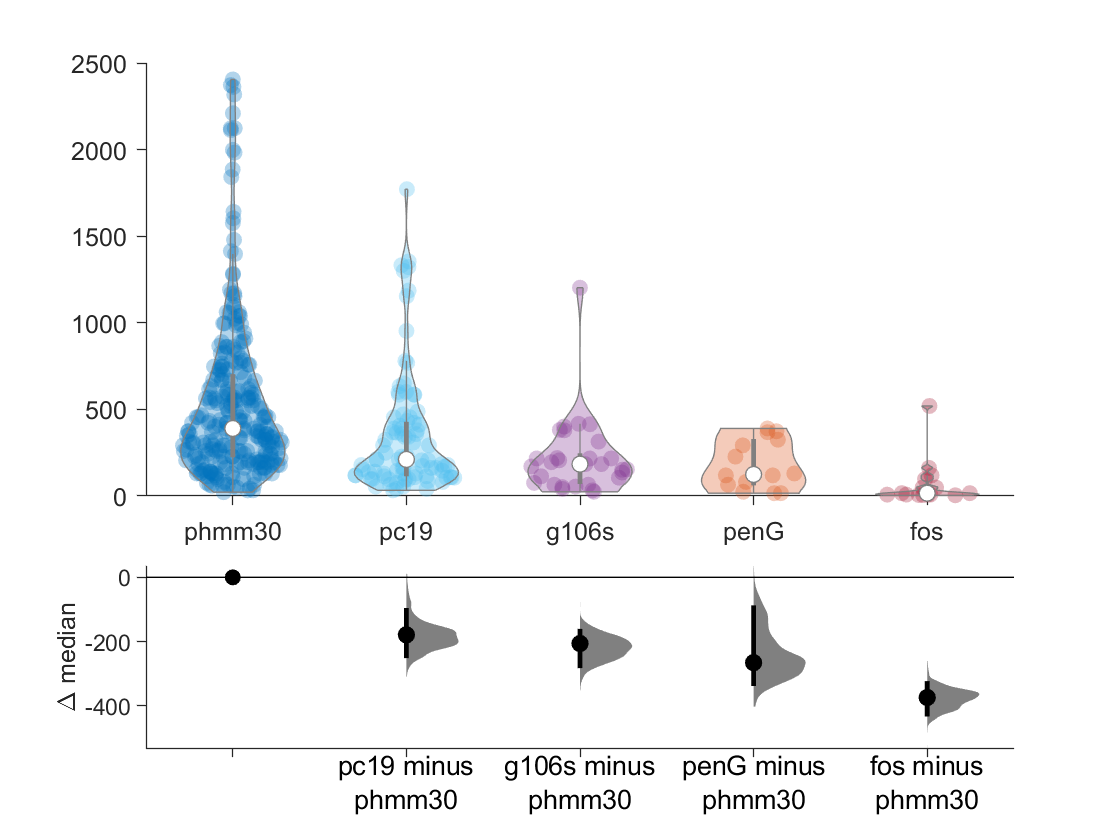

ans = 9×4 table
            Group              Value            CIs             N 
    ______________________    _______    __________________    ___

    {'phmm30'            }        390     346.67        455    265
    {'pc19'              }     211.25     173.33     341.25     89
    {'g106s'             }     184.17     113.75     216.67     29
    {'penG'              }     124.58         65     308.75     14
    {'fos'               }      16.25      8.125      48.75     17
    {'pc19 minus phmm30' }    -178.75       -260        -65    NaN
    {'g106s minus phmm30'}    -205.83    -287.08    -151.67    NaN
    {'penG minus phmm30' }    -265.42    -349.38        -65    NaN
    {'fos minus phmm30'  }    -373.75    -438.75       -325    NaN



violinplusdabest([phmm30_full_proc; pc19_full_proc; g106s_full_proc; penG_full_proc; fos_full_proc], [c_phmm30_full_proc; c_pc19_full_proc; c_g106s_full_proc; c_penG_full_proc; c_fos_full_proc],{'phmm30', 'pc19', 'g106s', 'penG', 'fos'})